Finished fmincon in 0.4429 seconds.
Finished particleswarm in 0.0496 seconds.
Finished ga in 0.2851 seconds.
Finished patternsearch in 0.1738 seconds.


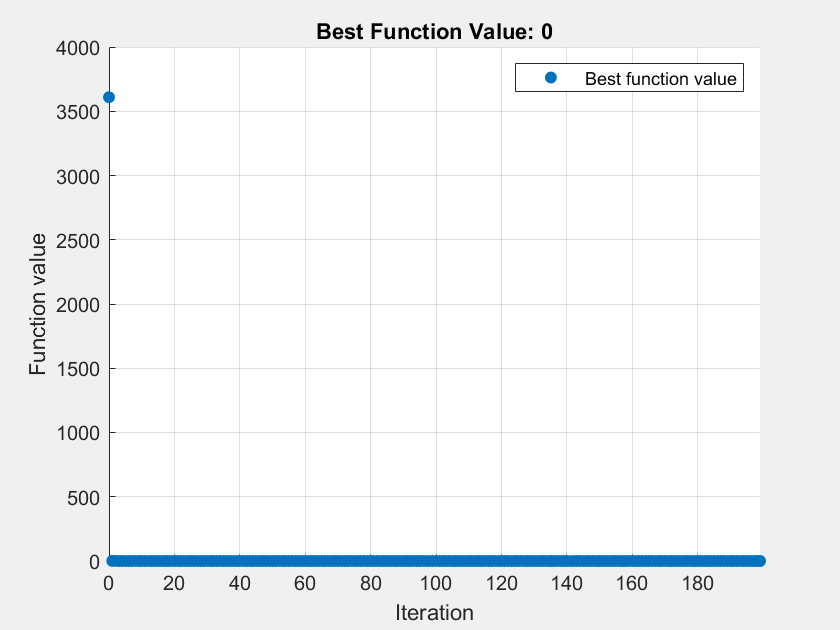

Finished surrogateopt in 50.0910 seconds.
Finished simulannealbnd in 1.2790 seconds.


% Define objective function (Rosenbrock Function)
fun = @(x) 100*(x(2) - x(1)^2)^2 + (1 - x(1))^2;

% Bounds and initial guess
lb = [-2, -2];
ub = [2, 2];
x0 = [0, 0]; 

optimizers = {'fmincon', 'particleswarm', 'ga', 'patternsearch', 'surrogateopt', 'simulannealbnd'};
numOpts = length(optimizers);
execTimes = zeros(1, numOpts);
solutions = cell(1, numOpts);

for i = 1:numOpts
    tic;
    switch optimizers{i}
        case 'fmincon'
            options = optimoptions('fmincon', 'Display', 'off');
            [sol, ~] = fmincon(fun, x0, [], [], [], [], lb, ub, [], options);
            
        case 'particleswarm'
            options = optimoptions('particleswarm', 'Display', 'off');
            [sol, ~] = particleswarm(fun, 2, lb, ub, options);
            
        case 'ga'
            options = optimoptions('ga', 'Display', 'off');
            [sol, ~] = ga(fun, 2, [], [], [], [], lb, ub, [], options);
            
        case 'patternsearch'
            options = optimoptions('patternsearch', 'Display', 'off');
            [sol, ~] = patternsearch(fun, x0, [], [], [], [], lb, ub, options);
            
        case 'surrogateopt'
            % FIXED: Create options object using optimoptions properly
            options = optimoptions('surrogateopt', 'Display', 'off');
            [sol, ~] = surrogateopt(fun, lb, ub, options);
            
        case 'simulannealbnd'
            options = optimoptions('simulannealbnd', 'Display', 'off');
            [sol, ~] = simulannealbnd(fun, x0, lb, ub, options);
    end
    execTimes(i) = toc;
    solutions{i} = sol;
    
    fprintf('Finished %s in %.4f seconds.\n', optimizers{i}, execTimes(i));
end

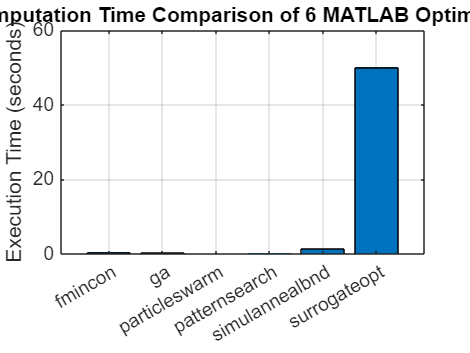


% Plotting Execution Times Benchmark
figure;
bar(categorical(optimizers), execTimes);
ylabel('Execution Time (seconds)');
title('Computation Time Comparison of 6 MATLAB Optimizers');
grid on;

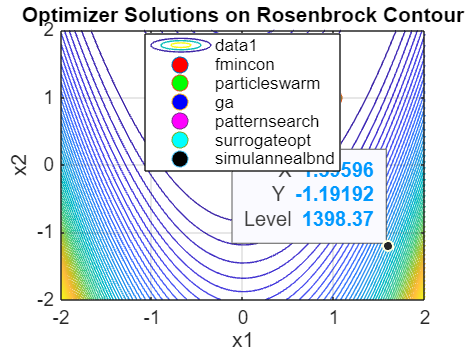


% Plotting the Rosenbrock Surface and Solutions
[X1, X2] = meshgrid(linspace(-2,2,100), linspace(-2,2,100));
Z = 100*(X2 - X1.^2).^2 + (1 - X1).^2;
figure;
contour(X1, X2, Z, 50); hold on;
colors = {'r', 'g', 'b', 'm', 'c', 'k'};
for i = 1:numOpts
    plot(solutions{i}(1), solutions{i}(2), 'o', 'MarkerFaceColor', colors{i}, 'MarkerSize', 8, 'DisplayName', optimizers{i});
end
legend('Location', 'best');
title('Optimizer Solutions on Rosenbrock Contour');
xlabel('x1'); ylabel('x2');
grid on;